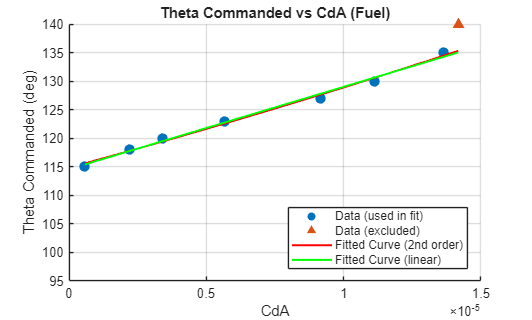

%% ========================================================================
%  EREG Valve Calibration: Theta Commanded vs CdA (Fuel & Oxidizer)
% =========================================================================

%% --- Valve travel limits (deg) ------------------------------------------
fuelClose    = 95;
fuelOpen     = 140;
fuelCracking = 108;

oxClose    = 0;
oxOpen     = 45;
oxCracking = 13;

% Commanded-angle offset between the fuel and ox valves on the test rig
commandDiff = oxClose - fuelClose;

%% --- Raw test data -------------------------------------------------------
thetaCommandedArrayFuel = [115 118 120 123 127 130 135 140];
thetaCommandedArrayOx   = thetaCommandedArrayFuel + commandDiff;

upstreamPressureArray   = [6.78 6.17 5.55 4.53 3.59 3.76 3.19 3.57] * 1e5;
downstreamPressureArray = [1.03 1.21 1.40 1.74 2.04 2.38 2.31 2.59] * 1e5;
mdotArray               = [0.0195 0.0691 0.0981 0.1336 0.1611 0.1845 0.1810 0.1984];

nFitPoints = numel(thetaCommandedArrayFuel) - 1;   % exclude final point from fitting only

%% --- Fuel EREG: relation struct + fits ------------------------------------
relationStructFuel = buildRelationStruct(thetaCommandedArrayFuel, upstreamPressureArray, ...
    downstreamPressureArray, mdotArray, fuelClose, fuelOpen);

save('CdARelationship.mat', 'relationStructFuel');

[allAnglesFuel, allCdAFuel, allKvsFuel] = unpackRelationStruct(relationStructFuel);

% Fit only on the first nFitPoints, excluding the last point
quadraticFitFuel  = polyfit(allCdAFuel(1:nFitPoints), allAnglesFuel(1:nFitPoints), 2);
linearFitFuel     = polyfit(allCdAFuel(1:nFitPoints), allAnglesFuel(1:nFitPoints), 1);
linearFitFuelTrans = polyfit(allAnglesFuel(1:nFitPoints), allCdAFuel(1:nFitPoints), 1);
linearFitFuelKv   = polyfit(allKvsFuel(1:nFitPoints), allAnglesFuel(1:nFitPoints), 1);

plotThetaVsCdA(allCdAFuel, allAnglesFuel, nFitPoints, quadraticFitFuel, linearFitFuel, ...
    fuelClose, fuelOpen, 'Fuel');

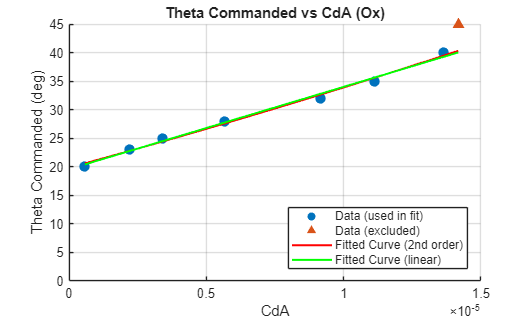


%% --- Oxidizer EREG: relation struct + fits --------------------------------
relationStructOx = buildRelationStruct(thetaCommandedArrayOx, upstreamPressureArray, ...
    downstreamPressureArray, mdotArray, oxClose, oxOpen);

save('CdARelationship.mat', 'relationStructOx', '-append');

[allAnglesOx, allCdAOx, allKvsOx] = unpackRelationStruct(relationStructOx);

quadraticFitOx   = polyfit(allCdAOx(1:nFitPoints), allAnglesOx(1:nFitPoints), 2);
linearFitOx      = polyfit(allCdAOx(1:nFitPoints), allAnglesOx(1:nFitPoints), 1);
linearFitOxTrans = polyfit(allAnglesOx(1:nFitPoints), allCdAOx(1:nFitPoints), 1);
linearFitOxKv    = polyfit(allKvsOx(1:nFitPoints), allAnglesOx(1:nFitPoints), 1);

plotThetaVsCdA(allCdAOx, allAnglesOx, nFitPoints, quadraticFitOx, linearFitOx, ...
    oxClose, oxOpen, 'Ox');


%% --- Fuel EREG: orifice area vs valve angle --------------------------------
[valveAngleArrayFuel, valveFractionVectorFuel, orificeAreaVectorFuel] = ...
    buildOrificeAreaVector(fuelClose, fuelOpen, fuelCracking, linearFitFuelTrans);

%% --- Oxidizer EREG: orifice area vs valve angle ----------------------------
[valveAngleArrayOx, valveFractionVectorOx, orificeAreaVectorOx] = ...
    buildOrificeAreaVector(oxClose, oxOpen, oxCracking, linearFitOxTrans);


%% ========================================================================
%  Local functions
% =========================================================================

function relationStruct = buildRelationStruct(thetaCommandedArray, upstreamPressureArray, ...
    downstreamPressureArray, mdotArray, valveClose, valveOpen)

    relationStruct = struct('thetaCommanded', {}, 'thetaPercentage', {}, 'dP', {}, 'CdA', {}, 'Kv', {});

    for i = 1:numel(thetaCommandedArray)
        thetaCommanded     = thetaCommandedArray(i);
        upstreamPressure   = upstreamPressureArray(i);
        downstreamPressure = downstreamPressureArray(i);
        mdot               = mdotArray(i);

        CdA = getCdAfromData(upstreamPressure, downstreamPressure, mdot, 1000);
        Kv  = CdA * 50900;
        thetaPercentage = (thetaCommanded - valveClose) * 100 / (valveOpen - valveClose);
        dP = (upstreamPressure - downstreamPressure) * 1e-05;

        relationStruct(i) = struct('thetaCommanded', thetaCommanded, ...
                                    'thetaPercentage', thetaPercentage, ...
                                    'dP', dP, ...
                                    'CdA', CdA, ...
                                    'Kv', Kv);
    end
end

function [allAngles, allCdA, allKvs] = unpackRelationStruct(relationStruct)
    allAngles = [relationStruct.thetaCommanded];
    allCdA    = [relationStruct.CdA];
    allKvs    = [relationStruct.Kv];
end

function plotThetaVsCdA(allCdA, allAngles, nFitPoints, quadraticFit, linearFit, valveClose, valveOpen, labelStr)
    figure;
    scatter(allCdA(1:nFitPoints), allAngles(1:nFitPoints), 60, 'filled', 'MarkerFaceColor', [0 0.4470 0.7410]);
    hold on;
    scatter(allCdA(end), allAngles(end), 60, 'filled', 'Marker', '^', 'MarkerFaceColor', [0.8500 0.3250 0.0980]);

    CdAFit         = linspace(min(allCdA), max(allCdA), 500);
    thetaFitQuad   = polyval(quadraticFit, CdAFit);
    thetaFitLinear = polyval(linearFit, CdAFit);

    plot(CdAFit, thetaFitQuad, 'r-', 'LineWidth', 1.5);
    plot(CdAFit, thetaFitLinear, 'g-', 'LineWidth', 1.5);

    xlabel('CdA');
    ylabel('Theta Commanded (deg)');
    title(sprintf('Theta Commanded vs CdA (%s)', labelStr));
    legend('Data (used in fit)', 'Data (excluded)', 'Fitted Curve (2nd order)', 'Fitted Curve (linear)', 'Location', 'best');
    grid on;
    ylim([valveClose valveOpen]);
    hold off;
end

function [valveAngleArray, valveFractionVector, orificeAreaVector] = ...
    buildOrificeAreaVector(valveClose, valveOpen, valveCracking, linearFitTrans)

    valveAngleArray     = linspace(valveClose, valveOpen, 100);
    valveFractionVector = (valveAngleArray - valveClose) / (valveOpen - valveClose);
    orificeAreaVector    = zeros(size(valveFractionVector));

    for i = 1:numel(valveAngleArray)
        Angle = valveAngleArray(i);
        if Angle <= valveCracking
            orificeAreaVector(i) = 1e-10 + 1e-11 * i;
        else
            orificeAreaVector(i) = max(1e-10 + 1e-11 * i, polyval(linearFitTrans, Angle));
        end
    end
end